clear all;clc;

## Load or specify category labels

addpath(genpath('../helperFunctions/'))

d = natsortfiles(dir('./behaviorData/shrewData.mat'));
load([d(end).folder,'/',d(end).name])

exp_colors = flipud([179,128,206;...
    211,107,172;...
    254,153,132;...
    248,214,86]/256);

trial_colors = [62,159,44;...
    14,144,201;...
    30,57,155]/256;


## Manipulate data

displayNSess = false;

% Determine which shrews to use
shrewname={'Seymour','Dominic','Ryker'};
shrewID = 1:3;

allTasks = {'Camel_v2_test_nn','Camel_novel_v2_test_nn','Camel_Rhino_test_nn','Camel_background_matrix'};

sessionNTrials = cell(length(allTasks),length(shrewname));
sessionNTarg = cell(length(allTasks),length(shrewname));
sessionAcc_Catch = cell(length(allTasks),length(shrewname));
sessionAcc_nonCatch = cell(length(allTasks),length(shrewname));
sessionAcc_test = cell(length(allTasks),length(shrewname));
sessionAcc_NovUnrew = cell(length(allTasks),length(shrewname));
sessionAcc_NovRew = cell(length(allTasks),length(shrewname));
sessionPerf_NovUnrew = cell(length(allTasks),length(shrewname));
sessionPerf_NovRew = cell(length(allTasks),length(shrewname));
sessionAcc_NovTarg = cell(length(allTasks),length(shrewname));
sessionAcc_NovDist = cell(length(allTasks),length(shrewname));
sessionAcc_NovBoth = cell(length(allTasks),length(shrewname));
sessionAcc_Familiar = cell(length(allTasks),length(shrewname));

for task = 1:length(allTasks)
    nTarg = length(unique(allData.(allTasks{task}).T_Expt_ID));
    
    targID = unique(allData.(allTasks{task}).T_Expt_ID);
    for ts = 1:length(shrewname)
        sessionIdx = unique(allData.(allTasks{task}).SessionID(allData.(allTasks{task}).ShrewID==ts));
        sessionNTrials{task,ts} = zeros(1,length(sessionIdx));
        sessionNTarg{task,ts} = zeros(1,length(sessionIdx));
        sessionAcc_Catch{task,ts} = zeros(1,length(sessionIdx));
        sessionAcc_nonCatch{task,ts} = zeros(1,length(sessionIdx));
        sessionAcc_NovUnrew{task,ts} = zeros(1,length(sessionIdx));
        sessionAcc_NovRew{task,ts} = zeros(1,length(sessionIdx));
        sessionPerf_NovUnrew{task,ts} = {};
        sessionPerf_NovRew{task,ts} = {};
        sessionAcc_NovTarg{task,ts} = zeros(1,length(sessionIdx));
        sessionAcc_NovDist{task,ts} = zeros(1,length(sessionIdx));
        sessionAcc_NovBoth{task,ts} = zeros(1,length(sessionIdx));
        sessionAcc_test{task,ts} = zeros(1,length(sessionIdx));
        sessionAcc_Familiar{task,ts} = zeros(1,length(sessionIdx));
        
        catchTrials = allData.(allTasks{task}).ctch == 1;
        noncatchTrials = allData.(allTasks{task}).ctch ~= 1;
        novUnrewTrials = isnan(allData.(allTasks{task}).ctch);
        novTargTrials = (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0;
        novDistTrials = (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0;
        novBothTrials = ((allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0 & (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0) |...
            ((allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).TestTarg)==0 & (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).TestDist)==0);
        anyNovTrials = (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0 | (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0 |...
            (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).TestTarg)==0 | (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).TestDist)==0;
        novRewTrials = (allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).NovelTarg)==0 | (allData.(allTasks{task}).D_Expt_ID - allData.(allTasks{task}).NovelDist)==0;
        famTrials = ~anyNovTrials & ~catchTrials;
        
        if displayNSess
            disp([allTasks{task},', ',shrewname{ts},', NTarg = ',num2str(length(unique(allData.(allTasks{task}).T_Expt_ID(allData.(allTasks{task}).ShrewID==ts))))])
            disp([allTasks{task},', ',shrewname{ts},', NDist = ',num2str(length(unique(allData.(allTasks{task}).D_Expt_ID(allData.(allTasks{task}).ShrewID==ts))))])
        end
        
        for ss = 1:length(sessionIdx)
            sessionAcc_Catch{task,ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & catchTrials),'omitnan');
            sessionAcc_nonCatch{task,ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & noncatchTrials),'omitnan');
            sessionAcc_NovUnrew{task,ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novUnrewTrials),'omitnan');
            sessionAcc_NovRew{task,ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novRewTrials),'omitnan');
            sessionAcc_NovTarg{task,ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novTargTrials),'omitnan');
            sessionAcc_NovDist{task,ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novDistTrials),'omitnan');
            sessionAcc_NovBoth{task,ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novBothTrials),'omitnan');
            sessionAcc_Familiar{task,ts}(ss) = mean(allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & famTrials),'omitnan');
            sessionNTrials{task,ts}(ss) = sum(allData.(allTasks{task}).SessionID==sessionIdx(ss));
            sessionNTarg{task,ts}(ss) = length(unique(allData.(allTasks{task}).T_Expt_ID(allData.(allTasks{task}).SessionID==sessionIdx(ss))));
            
            sessionPerf_NovUnrew{task,ts}{ss} = allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novUnrewTrials);
            sessionPerf_NovRew{task,ts}{ss} = allData.(allTasks{task}).correct(allData.(allTasks{task}).SessionID==sessionIdx(ss) & novRewTrials);
        end
    end
end

## Performance Summary Figure

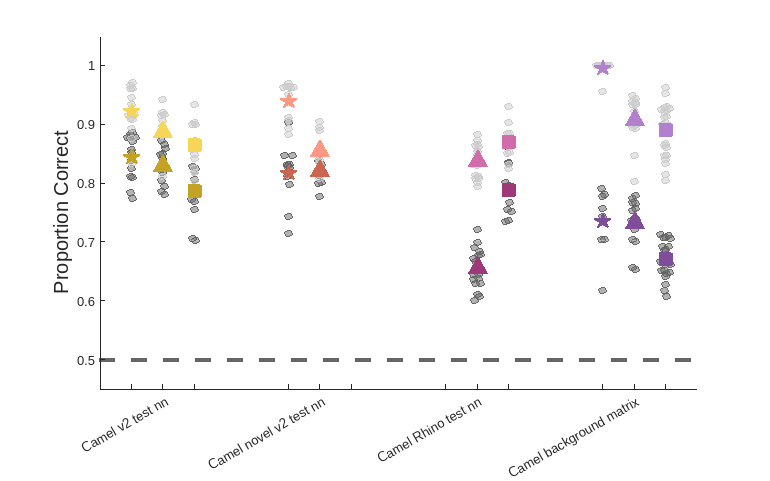

shrewcolor_exp = [0.4,0.4,0.4;...
    0.4,0.4,0.4;...
    0.4,0.4,0.4];

shrewcolor_ctch = [0.8,0.8,0.8;...
    0.8,0.8,0.8;...
    0.8,0.8,0.8];

shrewmarker = {'pentagram','^','s'};

figure('Renderer', 'painters', 'Position', [10 10 800 500]); hold on;
for task = 1:length(allTasks)
    xvalues = 5*task-4:5*task-2;
    mean_noncatch = cellfun(@nanmean,sessionAcc_nonCatch(task,:));
    mean_catch = cellfun(@nanmean,sessionAcc_Catch(task,:));
    ax = plotSpread(sessionAcc_nonCatch(task,:),'distributionMarkers','o',...
        'distributionColors',shrewcolor_exp,...
        'xValues',xvalues,...
        'xNames',{' ',allTasks{task},' '},...
        'categoryLabels',shrewname,...
        'binWidth',0.2);
    
    plotSpread(sessionAcc_Catch(task,:),'distributionMarkers','o',...
        'distributionColors',shrewcolor_ctch,...
        'xValues',xvalues,...
        'xNames',{' ',allTasks{task},' '});
    
    for i = 1:length(xvalues)
        plot(xvalues(i),mean_noncatch(i),'Color',exp_colors(task,:)-0.2,'Marker',shrewmarker{i},'MarkerFaceColor',exp_colors(task,:)-0.2,'MarkerSize',12,'linewidth',1.7);
        plot(xvalues(i),mean_catch(i),'Color',exp_colors(task,:),'Marker',shrewmarker{i},'MarkerFaceColor',exp_colors(task,:),'MarkerSize',12,'linewidth',1.7);
    end
end

ax{3}.XTick = [1:3,6:8,11:13,16:18];
ax{3}.XTickLabel = {' ',strrep(allTasks{1},'_',' '),' ',' ',strrep(allTasks{2},'_',' '),' ',' ',strrep(allTasks{3},'_',' '),' ',' ',strrep(allTasks{4},'_',' '),' '};
ylim([0.45 1.05])
yticks(0.5:0.1:1)
ylabel('Proportion Correct','fontsize',15)

yline(0.5,'--','LineWidth',3)

## Performance of Novel Unrewarded & Novel Rewarded

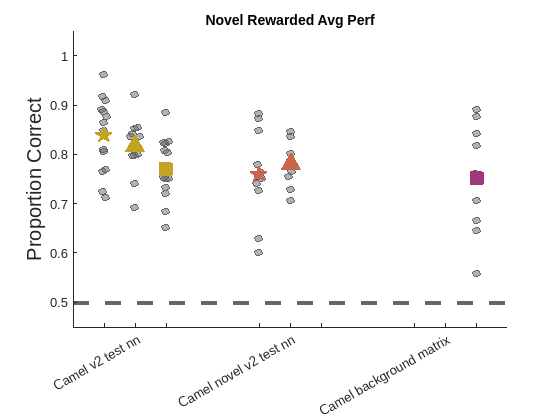

incTask = 1:3;

figure; hold on;
for task = 1:length(allTasks)-1
    xvalues = 5*task-4:5*task-2;
    mean_novrew = cellfun(@nanmean,sessionAcc_NovRew(incTask(task),:));
    ax = plotSpread(sessionAcc_NovRew(incTask(task),:),'distributionMarkers','o',...
        'distributionColors',shrewcolor_exp,...
        'xValues',xvalues,...
        'xNames',{' ',allTasks{incTask(task)},' '},...
        'categoryLabels',shrewname,...
        'binWidth',0.2);

    for i = 1:length(xvalues)
        plot(xvalues(i),mean_novrew(i),'Color',exp_colors(incTask(task),:)-0.2,'Marker',shrewmarker{i},'MarkerFaceColor',exp_colors(task,:)-0.2,'MarkerSize',12,'linewidth',1.7);
    end
end

ax{3}.XTick = [1:3,6:8,11:13,16:18];
ax{3}.XTickLabel = {' ',strrep(allTasks{1},'_',' '),' ',' ',strrep(allTasks{2},'_',' '),' ',' ',strrep(allTasks{4},'_',' '),' '};
ylim([0.45 1.05])
yticks(0.5:0.1:1)
ylabel('Proportion Correct','fontsize',15)

yline(0.5,'--','LineWidth',3)
title('Novel Rewarded Avg Perf')

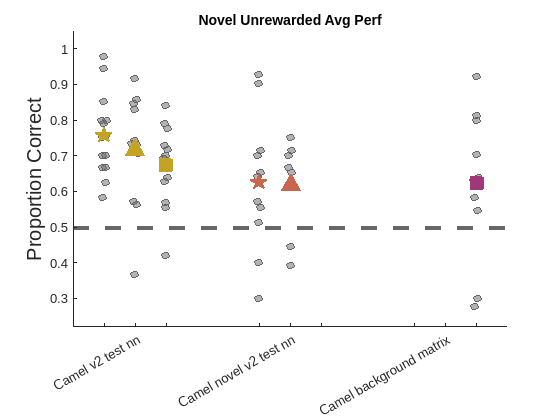


figure; hold on;
for task = 1:length(allTasks)-1
    xvalues = 5*task-4:5*task-2;
    mean_novunrew = cellfun(@nanmean,sessionAcc_NovUnrew(incTask(task),:));
    ax = plotSpread(sessionAcc_NovUnrew(incTask(task),:),'distributionMarkers','o',...
        'distributionColors',shrewcolor_exp,...
        'xValues',xvalues,...
        'xNames',{' ',allTasks{incTask(task)},' '},...
        'categoryLabels',shrewname,...
        'binWidth',0.2);

    for i = 1:length(xvalues)
        plot(xvalues(i),mean_novunrew(i),'Color',exp_colors(incTask(task),:)-0.2,'Marker',shrewmarker{i},'MarkerFaceColor',exp_colors(task,:)-0.2,'MarkerSize',12,'linewidth',1.7);
    end
end

ax{3}.XTick = [1:3,6:8,11:13,16:18];
ax{3}.XTickLabel = {' ',strrep(allTasks{1},'_',' '),' ',' ',strrep(allTasks{2},'_',' '),' ',' ',strrep(allTasks{4},'_',' '),' '};
ylim([0.22 1.05])
yticks(0.3:0.1:1)
ylabel('Proportion Correct','fontsize',15)

yline(0.5,'--','LineWidth',3)
title('Novel Unrewarded Avg Perf')

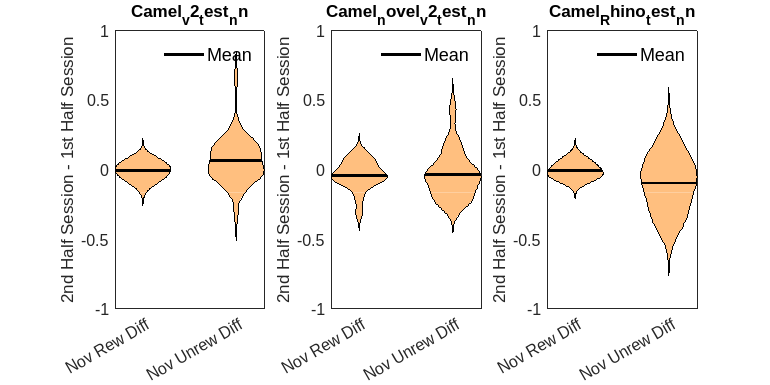

figure('Renderer', 'painters', 'Position', [10 10 800 400]);
for task = 1:length(allTasks)-1
    subplot(1,length(allTasks)-1,task); hold on;
    novrew_all = [];
    novunrew_all = [];
    for shrew = 1:length(shrewID)
        nSess = length(sessionPerf_NovRew{task,shrew});
        novrew_perfhalf = nan(nSess,2);
        for ss = 1:nSess
            max_length = length(sessionPerf_NovRew{task,shrew}{ss});
            novrew_perfhalf(ss,1) = mean(sessionPerf_NovRew{task,shrew}{ss}(1:round(max_length/2)),'omitnan');
            novrew_perfhalf(ss,2) = mean(sessionPerf_NovRew{task,shrew}{ss}(round(max_length/2)+1:end),'omitnan');
        end
        mean_novrew = mean(novrew_perfhalf,1,'omitnan');
        novrew_all = [novrew_all;novrew_perfhalf];
        
        nSess = length(sessionPerf_NovUnrew{task,shrew});
        novunrew_perfhalf = nan(nSess,2);
        for ss = 1:nSess
            max_length = length(sessionPerf_NovUnrew{task,shrew}{ss});
            novunrew_perfhalf(ss,1) = mean(sessionPerf_NovUnrew{task,shrew}{ss}(1:round(max_length/2)),'omitnan');
            novunrew_perfhalf(ss,2) = mean(sessionPerf_NovUnrew{task,shrew}{ss}(round(max_length/2)+1:end),'omitnan');
        end
        mean_novunrew = mean(novunrew_perfhalf,1,'omitnan');
        novunrew_all = [novunrew_all;novunrew_perfhalf];
        
    end
    violin([novrew_all(:,2) - novrew_all(:,1), novunrew_all(:,2) - novunrew_all(:,1)],'medc',[]);
    xlim([0.7 2.3])
    ylim([-1 1])
    xticks([1,2])
    xticklabels({'Nov Rew Diff','Nov Unrew Diff'})
    ylabel('2nd Half Session - 1st Half Session')
    title(allTasks{task})
end

## Avg performance for novel stim trial types

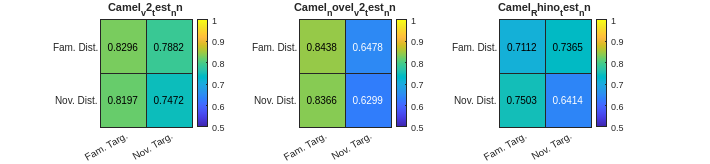

sessType = 1;

data = cell(2,2);
for ts = 1:3
    data{1,1} = [data{1,1} sessionAcc_Familiar{sessType,ts}];
    data{1,2} = [data{1,2} sessionAcc_NovTarg{sessType,ts}];
    data{2,1} = [data{2,1} sessionAcc_NovDist{sessType,ts}];
    data{2,2} = [data{2,2} sessionAcc_NovBoth{sessType,ts}];
end

perf = cellfun(@(x) mean(x,'omitnan'), data);
x = {'Fam. Targ.','Nov. Targ.'};
y = {'Fam. Dist.','Nov. Dist.'};

figure('Renderer', 'painters', 'Position', [10 10 1300 300]);
subplot(1,3,1)
heatmap(x,y,perf)
caxis([0.5 1])
title(allTasks{sessType})

sessType = 2;

data = cell(2,2);
for ts = 1:3
    data{1,1} = [data{1,1} sessionAcc_Familiar{sessType,ts}];
    data{1,2} = [data{1,2} sessionAcc_NovTarg{sessType,ts}];
    data{2,1} = [data{2,1} sessionAcc_NovDist{sessType,ts}];
    data{2,2} = [data{2,2} sessionAcc_NovBoth{sessType,ts}];
end

perf = cellfun(@(x) mean(x,'omitnan'), data);
x = {'Fam. Targ.','Nov. Targ.'};
y = {'Fam. Dist.','Nov. Dist.'};

subplot(1,3,2)
heatmap(x,y,perf)
caxis([0.5 1])
title(allTasks{sessType})

sessType = 3;

data = cell(2,2);
for ts = 1:3
    data{1,1} = [data{1,1} sessionAcc_Familiar{sessType,ts}];
    data{1,2} = [data{1,2} sessionAcc_NovTarg{sessType,ts}];
    data{2,1} = [data{2,1} sessionAcc_NovDist{sessType,ts}];
    data{2,2} = [data{2,2} sessionAcc_NovBoth{sessType,ts}];
end

perf = cellfun(@(x) mean(x,'omitnan'), data);
x = {'Fam. Targ.','Nov. Targ.'};
y = {'Fam. Dist.','Nov. Dist.'};

subplot(1,3,3)
heatmap(x,y,perf)
colormap(parula)
caxis([0.5 1])
title(allTasks{sessType})

## # Trials per Session Histogram

ntr = [];
for i = 1:4
    for j = 1:3
        ntr = [ntr sessionNTrials{i,j}];
    end
end
ntr_mean = mean(ntr);
ntr_median = median(ntr)

ntr_median = 862

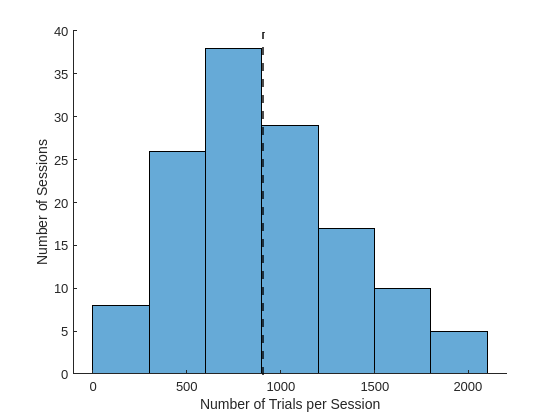


figure;
histogram(ntr)
xline(ntr_mean,'k--','LineWidth',1.5)
xlabel('Number of Trials per Session')
ylabel('Number of Sessions')
box off;

fprintf('Mean # Trials = %g, Total # Sessions = %g',ntr_mean,length(ntr))

Mean # Trials = 908.632, Total # Sessions = 133